# Design Trajectory Controller for UR5e Manipulator Using Simulink and Unreal Engine Co-simulation

This example shows how to design a trajectory controller using Simulink for a UR5e Manipulator. It also shows how to simulate the controller with the UR5e Manipulator robot in Unreal Engine 3-D simulation environment.

## Create a Scene in Unreal Engine

3-D simulation scene containing UR5e, sensors, and surrounding objects has been pre-configured for use in this example. You run the pre-configured scene in Unreal Engine and use it as a plant to design trajectory controller.

Download UR5e meshes from UniversalRobots Github® repository [here](https://github.com/UniversalRobots/Universal_Robots_ROS2_Description.git).

Place the UR5e meshes in the "mesh" folder under "Action" directory. Unreal engine uses these meshes to create the UR5e manipulator during simulation.

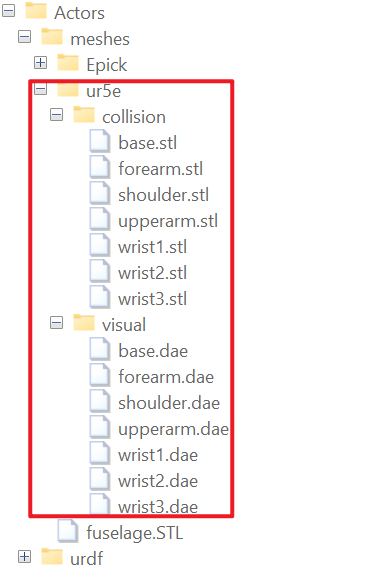

To validate mesh files and load required variables into MATLAB workspace.

helperSetupSim3DScene

To learn more about modeling in Unreal Engine, see [Simulation 3D Scene Configuration](docid:robotics_ref#mw_96a521fd-316f-497b-bc01-b2c5f4083563) block documentation.

Open the Simulink model

open_system("ShapeTracingSimExample")

With Simulation 3D Camera block and Simulation 3D Lidar block, you can access real time simulation sensor data such as images and point clouds from Simulink.

In this example, Simulation 3D Robot is configured to be the Universal Robot UR5e. During simulation, you can use `Config` input to pass joint position configuration for the manipulator. 

To customize the location of sensors, double check the corresponding blocks and modify the block parameters.

## Design Robot Controller in Simulink

In this example, the `ShapeTracingSimExample` captures the shape of a section of fuselage as point cloud data. During the first time step of simulation, the `helperGenerateJointConfig `function uses the point cloud data to generate a set of joint configurations for the robot to follow.

In the controller area, this set of joint configurations is passed in as input to the Minimum Jerk Polynomial Trajectory block to obtain a 6-by-1 array that represents all joint positions at each time step. The joint configuration input to the Simulation 3D robot block then moves the UR5e manipulator in the Unreal engine scene to the corresponding configuration.

  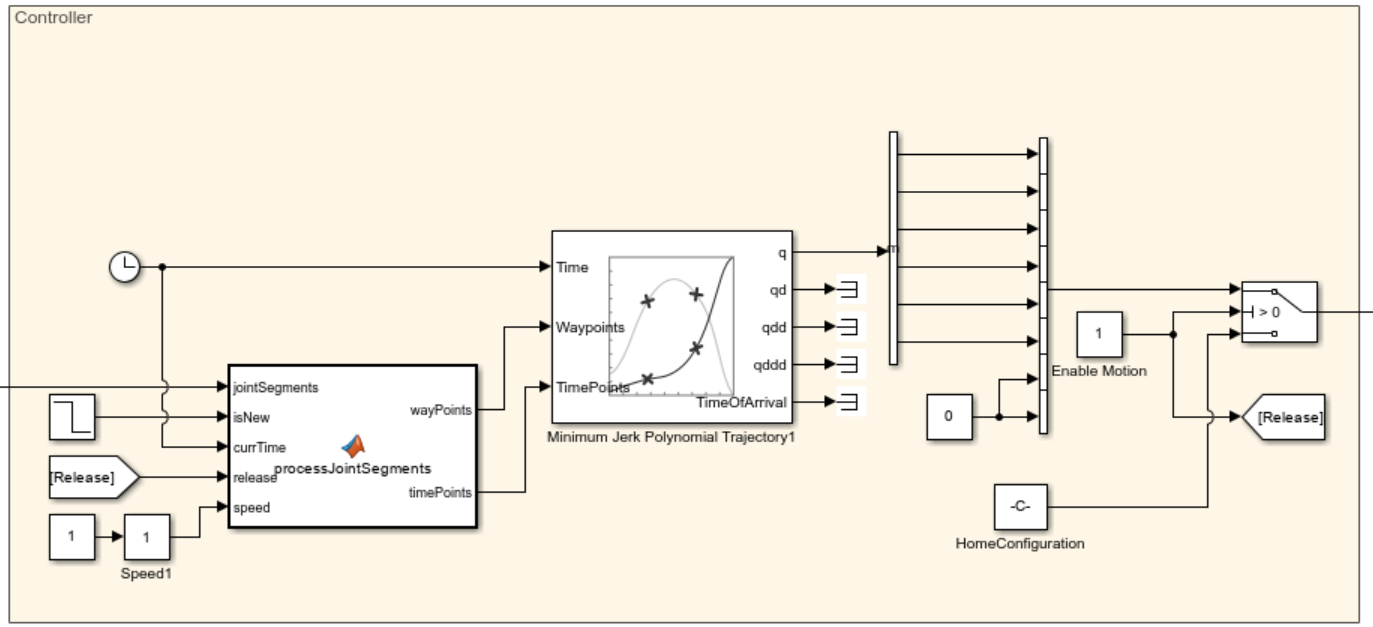

## Test the Controller with Unreal Engine Simulation

Run the simulation and observe the manipulator motion in Unreal Engine

sim("ShapeTracingSimExample")

Pose error 0.01 in index 26 at coordinate 0.08 0.81 0.09
Pose error 0.02 in index 31 at coordinate 0.14 0.86 0.09
Pose error 0.04 in index 43 at coordinate 0.24 0.81 0.09
Pose error 0.04 in index 47 at coordinate 0.28 0.41 0.08
Pose error 0.02 in index 50 at coordinate 0.31 0.48 0.07
Pose error 0.02 in index 52 at coordinate 0.33 0.51 0.07
Pose error 0.02 in index 56 at coordinate 0.35 0.53 0.07


Size mismatch for MATLAB expression '<output of helperGenerateJointConfig>'. Expected = 6x120, actual = 6x68.

During simulation, you can

- Tune the "Speed" block (Slider Gain) to control how quickly the manipulator moves

- Tune the "Enable Motion" block (Constant) to decide whether to lock the joints

Observes the behavior changes in Unreal Engine scene.

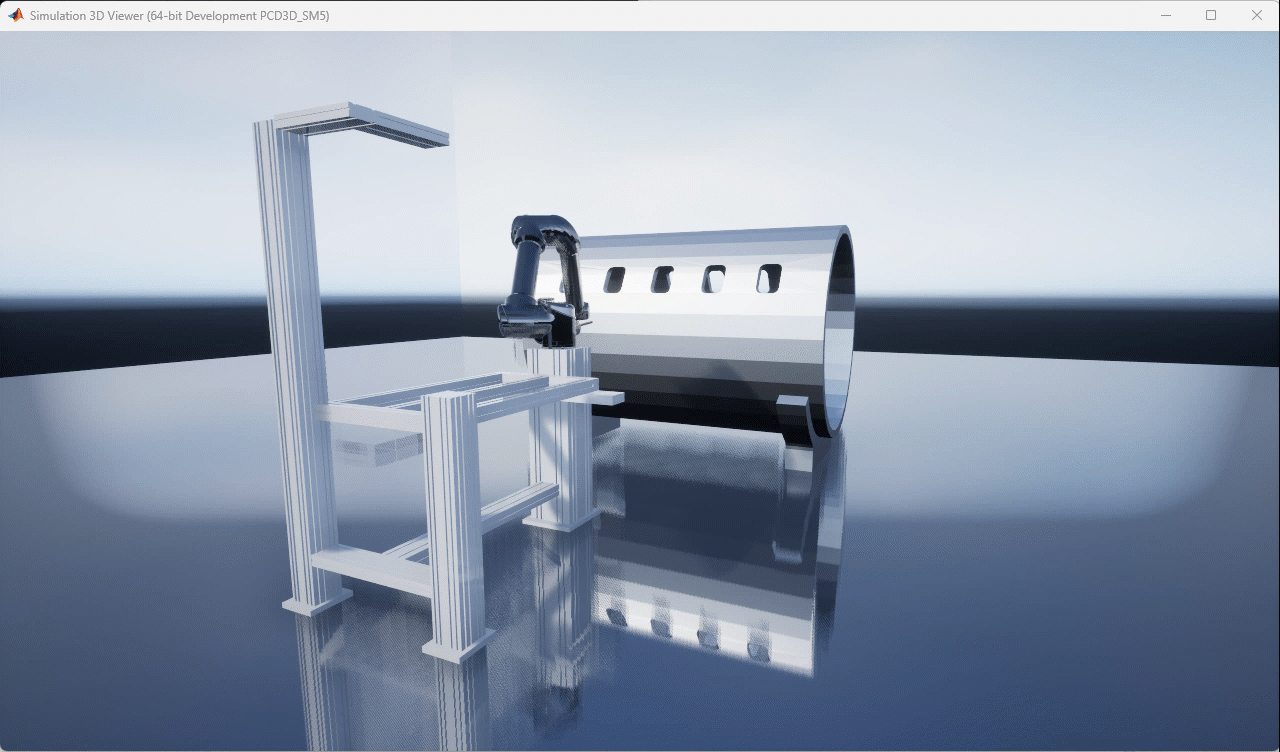

*Copyright 2024 The MathWorks, Inc.*